% Read image
clc
clear

N = 16;

for i = 1:N
    if (i < 10)
        number = '0' + string(i);
    else
        number = string(i);
    end
    
    name = './DB1/db1_' + number + '.jpg';
    
    RGB = imread(name);
    
    croppedImage = faceDetection(RGB);
    
    grayImage = im2gray(croppedImage);
    
    image_vector(:,i) = grayImage(:);
     
end

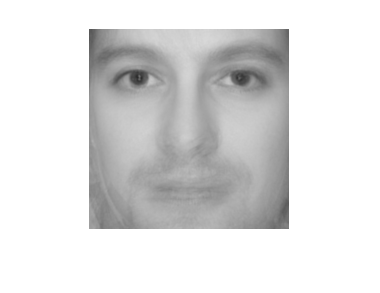

% Mean-face
meanFace = sum(image_vector,2)/N;
meanFaceImage = reshape(meanFace, 200, 200)/255;
imshow(meanFaceImage);


% Subtract mean
A = im2double(image_vector)-(meanFace/255);

% Covariance 
% C = AA';
C1 = A'*A;

[V, D] = eig(C1);

u = A*V;

uu = reshape(u,[200 200 16])

uu = uu(:,:,1) =

   1.0e-15 *

    0.2121    0.4514    0.4157    0.4344    0.2502    0.3597    0.3308    0.4188    0.3469    0.3525    0.2925    0.1647    0.4164    0.1142    0.2235    0.3161    0.3912    0.4363    0.3986    0.2452    0.3675    0.1284    0.2638    0.2973    0.4419    0.2003    0.2369    0.2635    0.3880    0.1670   -0.0139    0.1730    0.1263    0.1018    0.1920    0.3033   -0.1033   -0.0417    0.0878    0.1162    0.1668    0.2105    0.2357    0.2081    0.1162    0.2385    0.2635   -0.1242   -0.1048    0.0907    0.0845    0.2036    0.1670    0.1373   -0.1262   -0.1088   -0.1864   -0.1074   -0.1636   -0.1897   -0.1033    0.0445    0.0342   -0.0251   -0.0732   -0.1213   -0.1072   -0.0791   -0.0740   -0.0827    0.3524    0.2860   -0.0370    0.0035    0.0709    0.1682    0.0677    0.0096    0.0532    0.0789    0.1037    0.0522   -0.0353    0.0162    0.0115    0.0910   -0.0041   -0.0064   -0.0425   -0.1105   -0.0677   -0.0080    0.0280    0.0421    0.0290   -0.0317    0.09

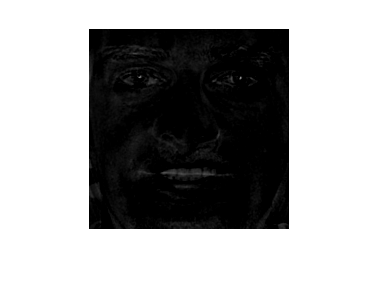


uu = uu(:,:,2:16);

imshow(uu(:,:,1))

w = u'*A;

aproximatedImage = meanFace + (u(:,1) .* w(:,1));

Matrix dimensions must agree.


imshow(reshape(aproximatedImage,[200 200]));

function croppedImage = faceDetection(RGB)
    % White balance
    rgbImageWhite = cWhitePatch(RGB);
    
    % Face mask
    mask = faceMask(rgbImageWhite);
    % disp('Face mask'), imshow(mask);
    
    % Eye map
    map = eyeMap(rgbImageWhite);
    % disp('Eye map'), imshow(eyeMap);
    
    % Combine
    res = map & mask;
    % disp('Eye map + face mask'), imshow(res);
    
    % Cleaning
    res = cleaning(res);
    
    % Get eye coordinates
    [lab,num]=bwlabel(res);
    stats = regionprops(lab);
    eye1 = getfield(stats,{1},'Centroid');
    y1 = eye1(1);
    x1 = eye1(2);
    eye2 = getfield(stats,{2},'Centroid');
    y2 = eye2(1);
    x2 = eye2(2);
    
    % Rotate the images based on the eyes
    rotatedImage = rotate_image(RGB,y1,x1,y2,x2);
    % disp('Rotated image'), imshow(rotatedImage);
    
    % Get new eye coordinates
    map = rotate_image(res,y1,x1,y2,x2);
    [lab,num]=bwlabel(map);
    stats2 = regionprops(lab);
    eye1 = getfield(stats2,{1},'Centroid');
    eye2 = getfield(stats2,{2},'Centroid');
    x1 = eye1(1);
    y1 = eye1(2);
    x2 = eye2(1);
    y2 = eye2(2);
    
    % Crop the image square for eigenfaces
    croppedImage = crop(rotatedImage, x1, y1, x2, y2);
end